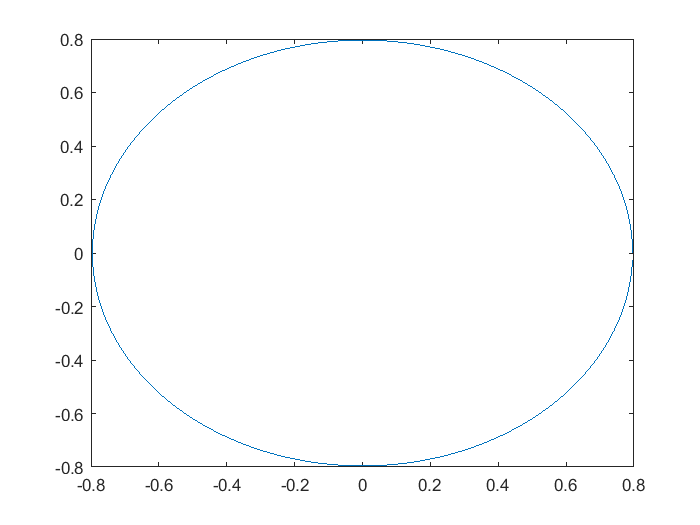

%%  МИУ

close all;
clear variables;
%% 
% Входные параметры

%  1 - входные данные 
k0 = 2*pi;
% Параметры среды-1
e = 2.56;
mu = 1;
k = k0*sqrt(mu*e);
eta = 120*pi*sqrt(mu/e);


% Параметры программы
a = 5/(2*pi);  % радиус круга
N = 200; % количество точек на круга
phi_i_grad = 0; % угол падения [град]
phi_i_rad = 2*pi/360*phi_i_grad; % угол падения [рад]
gamma = 1.781072417990;

% ========================================================================
%  Построение круга
dphi_grad = 360/N; % угловой шаг на круга [град]
dphi_rad =  2*pi/360*dphi_grad; % угловой шаг на круга [рад]
dx = 2*a*sin(dphi_rad/2);

% круга в полярной системе координат (пусть будет)
% получение векторов углов и вектора ридиусов
phi_circl_rad = zeros(1, N);
phi_circl_grad = zeros(1, N);
a_for_graph = zeros(1, N);
for i = 1 : N
    phi_circl_rad(i) = (i-1)*dphi_rad + dphi_rad/2;
    phi_circl_grad(i) = (i-1)*dphi_grad + dphi_grad/2;
    a_for_graph(i) = a;
end
%% 
% Генерация точек

dphi_grad = 360/N;
x = zeros(1,N);
z = zeros(1,N);

for i = 1 : N
    z(i) = a*sind(dphi_grad*(i-1));
    x(i) = a*cosd(dphi_grad*(i-1));
end

plot(x,z)

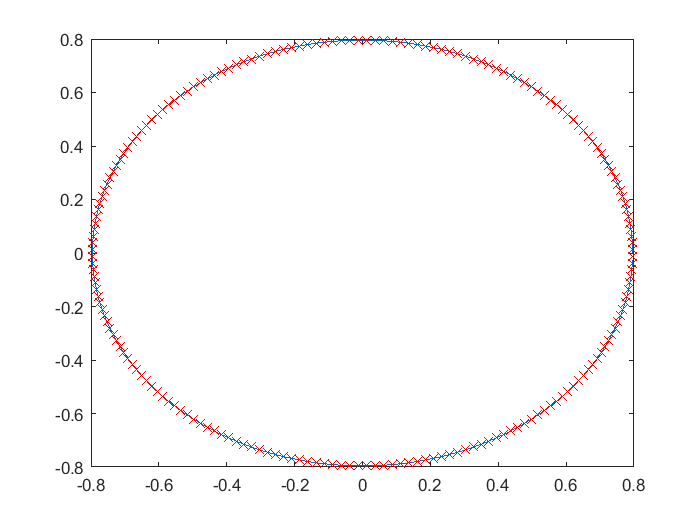

%% 
% Посчитаем t для каждого отрезка

for i = 1 : N
    if i == N
        tx(i) = -((x(1)-x(i)))/dx;
        tz(i) = -((z(1)-z(i)))/dx;
    else
        tx(i) = -(x(i+1)-x(i))/dx;
        tz(i) = -(z(i+1)-z(i))/dx;
    end
end
%% 
% Посчитаем n для каждого отрезка

%  Посчитаем n для каждого отрезка
%  нормальный вектор найдем с помощью матрицы повороты
    alpha = -90;
    matrix = [cosd(alpha),-sind(alpha); sind(alpha),cosd(alpha)];

for i = 1 : N
     matrix_temp = [tx(i), tz(i)]*matrix;
     nx(i) = matrix_temp(1);
     nz(i) = matrix_temp(2);
end
%% 
% Координаты центров отрезков

for i = 1 : N 
    if i == N
        x_midle(i) = ((x(1)+x(i)))/2;
        z_midle(i) = ((z(1)+z(i)))/2;
    else
        x_midle(i) = (x(i+1)+x(i))/2;
        z_midle(i) = (z(i+1)+z(i))/2;
    end    
end

plot(x,z,x_midle, z_midle, 'rx');

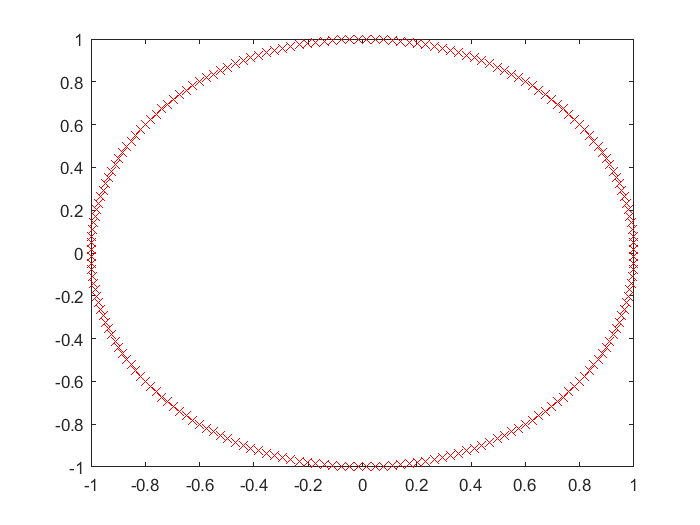


% визуализируем tx и tz
plot(tx, tz, 'rx');

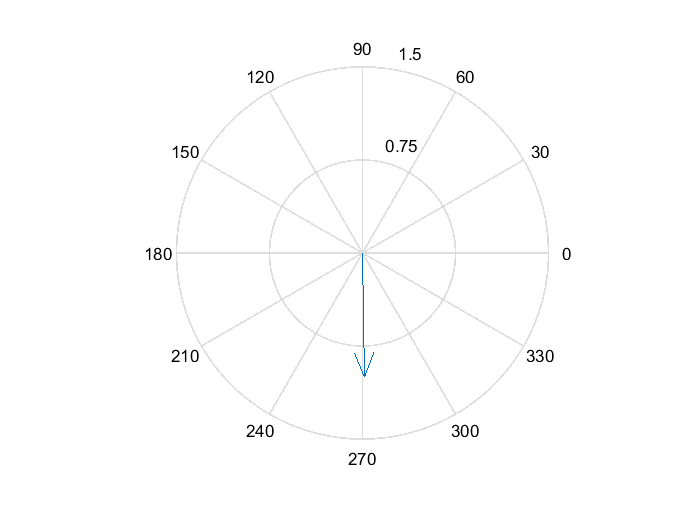

compass(tx(1),tz(1));

Падающее поле 

Ei = zeros(N,1);
Hi = zeros(N,1);
% падающее поле 
for m = 1 : N
    xm = x_midle(m);
    zm = z_midle(m);
    txm = tx(m);
    tzm = tz(m);

    % cоставляющие полей
    cx = -1i*k*cosd(phi_i_grad);
    cz = -1i*k*sind(phi_i_grad);
    
    Hiy = exp(cx*xm+cz*zm);
    Eix = - eta*sind(phi_i_grad) * Hiy;
    Eiz = + eta*cosd(phi_i_grad) * Hiy;
    
    % элементы системы  
    Hi(m) = Hiy;
    Ei(m) = txm*Eix + tzm*Eiz;
end  

## Алгоритм расчета Ae MFIE Hpol

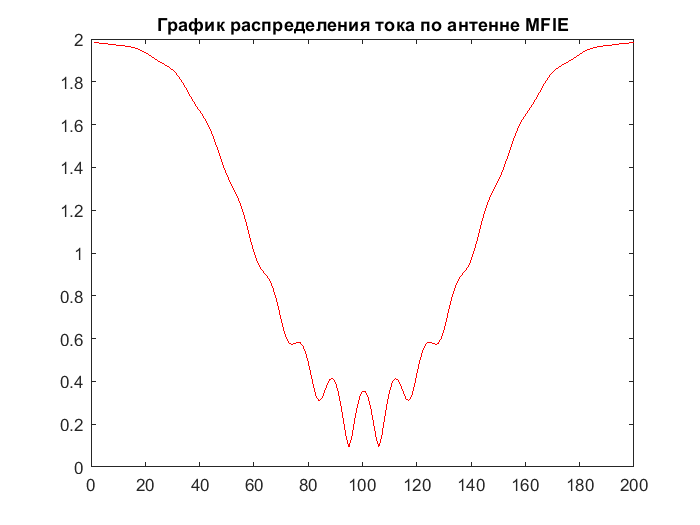

% 3 - cам ходя расчета 
% списик для хранения элементов системы 
    
for m  = 1 : N
    xm = x_midle(m);
    zm = z_midle(m);
    txm = tx(m);
    tzm = tz(m);
    nxm = nx(m);
    nzm = nz(m);
    
    for n = 1 : N
        xn = x_midle(n);
        zn = z_midle(n);
        txn = tx(n);
        tzn = tz(n);
        nxn = nx(n);
        nzn = nz(n);
%         dx = dx_mass(n);
            
        % Растояние между началом координат О2 и точкой наблюдений (в ГСК)        
        x_mO2 = xm - xn;
        z_mO2 = zm - zn;
        
        % Положим этот вектор на новую СК
        % Координаты этой точки (в ЛСК)
        umn = x_mO2*txn + z_mO2*tzn;
        wmn = x_mO2*nxn + z_mO2*nzn;
        
        % локальные замены 
        xmn = xm - xn;
        zmn = zm - zn;
        r = sqrt(xmn^2 + zmn^2);
        
        umn_plus = umn + dx/2;
        umn_minus = umn - dx/2; 
        r_minus = sqrt(umn_minus^2 + wmn^2);
        r_plus = sqrt(umn_plus^2 + wmn^2);
        rmn = sqrt(umn^2 + wmn^2);
        
        if n == m 
            % cоставляющие Hy1
            he_y1 =  - 1/2;
        elseif abs(n-m) <= 1.5 
            he_y1 =  - (1i/8*wmn*k^2*dx + 1/(2*pi)*(atan(umn_plus/wmn) - atan(umn_minus/wmn)));
        else 
            % cоставляющие Hy1
            he_y1 = - 1i/4*k*dx*(wmn/rmn*besselh(1,1,k*rmn));
        end
        H1y = he_y1;
        
%       символ кронкера
        if m == n
            kronker = 1;
        else 
            kronker = 0;
        end
        
        % расчет матричнх элементов 
        Zmn(m,n) = kronker + H1y;
    end
end

% расчеток токов ВИ 
I_Ae_MFIE = Zmn\Hi;

figure;
fig = plot(1:N, abs(I_Ae_MFIE), 'r');
title('График распределения тока по антенне MFIE'); 

## Алгоритм расчета Ae EFIE Hpol

% for m  = 1 : N
%     xm = x_midle(m);
%     zm = z_midle(m);
%     txm = tx(m);
%     tzm = tz(m);
%     nxm = nx(m);
%     nzm = nz(m);
%     
%     for n = 1 : N
%         xn = x_midle(n);
%         zn = z_midle(n);
%         txn = tx(n);
%         tzn = tz(n);
%         nxn = nx(n);
%         nzn = nz(n);
% %         dx = dx_mass(n);
%             
%         % Растояние между началом координат О2 и точкой наблюдений (в ГСК)        
%         x_mO2 = xm - xn;
%         z_mO2 = zm - zn;
%         
%         % Положим этот вектор на новую СК
%         % Координаты этой точки (в ЛСК)
%         umn = x_mO2*txn + z_mO2*tzn;
%         wmn = x_mO2*nxn + z_mO2*nzn;
%         
%         % локальные замены 
%         xmn = xm - xn;
%         zmn = zm - zn;
%         r = sqrt(xmn^2 + zmn^2);
%         
%         umn_plus = umn + dx/2;
%         umn_minus = umn - dx/2; 
%         r_minus = sqrt(umn_minus^2 + wmn^2);
%         r_plus = sqrt(umn_plus^2 + wmn^2);
%         rmn = sqrt(umn^2 + wmn^2);
%         
%         Hus = 0;
%         Hws = 0;
%         
%         if n == m 
%             % cоставляющие E1u
%             fe_u12 = 1i/4*dx*(1 + 1i*2/pi*(log(gamma*k*dx/4)-1)); 
%        elseif abs(n-m) <= 1.5 
%             hm_y1 = dx + 2*1i/pi * (wmn*(atan(umn_plus/wmn) - atan(umn_minus/wmn))...
%             + umn_plus*log(gamma*k/2*sqrt(umn_plus^2+wmn^2))...
%             - umn_minus*log(gamma*k/2*sqrt(umn_minus^2+wmn^2)) - dx);
%             hm_y1 = hm_y1 * 1i/4; % домножение на коэфицент
%             fe_u12 = hm_y1;
%         else 
%             % cоставляющие E1u
%             fe_u12 = 1i/4*dx*besselh(0,1,k*rmn);
%         end
%         % cоставляющие E1u
%         fe_u11 = - 1i/4*k*(umn_plus/r_plus*besselh(1,1,k*r_plus) - umn_minus/r_minus*besselh(1,1,k*r_minus));
%         % cоставляющие E1w
%         fe_w1 = - 1i/4*k*(wmn/r_plus*besselh(1,1,k*r_plus) - wmn/r_minus*besselh(1,1,k*r_minus));
%         
%         %% СОБЕРЕМ ВСЕ ВМЕСТЕ
%         E1u = 1i*eta/k*(fe_u11 + k^2*fe_u12);
%         E1w = 1i*eta/k*fe_w1;
%         
%         dot_tm_tn = (txm*txn+tzm*tzn);
%         dot_tm_nn = (txm*nxn+tzm*nzn);
%         Zmn(m,n) = dot_tm_tn*E1u + dot_tm_nn*E1w;
%     end
% end
% 
% I_Ae_EFIE = Zmn\Ei;
% 
% figure;
% fig = plot(1:N, abs(I_Ae_EFIE), 'r');
% title('График распределения тока по антенне EFIE'); 

% figure;
% plot(1:length(I_Ae_EFIE), abs(I_Ae_EFIE), 1:length(I_Ae_MFIE), abs(I_Ae_MFIE));

#### Алгоритм расчета Am MFIE Hpol

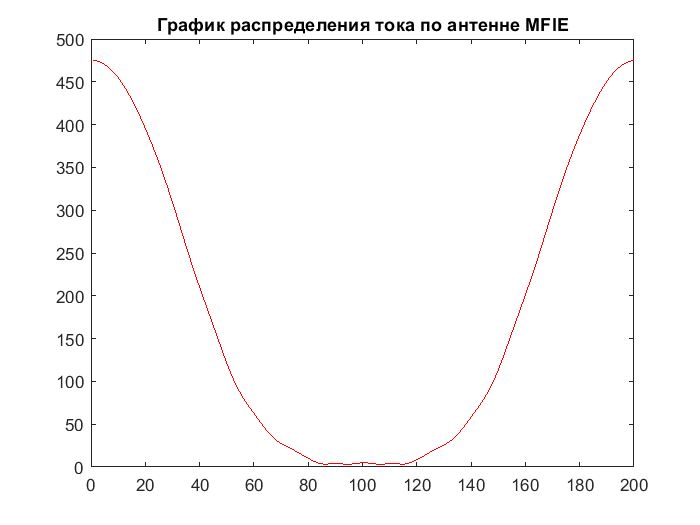

for m  = 1 : N
    xm = x_midle(m);
    zm = z_midle(m);
    txm = tx(m);
    tzm = tz(m);
    nxm = nx(m);
    nzm = nz(m);
    
    for n = 1 : N
        xn = x_midle(n);
        zn = z_midle(n);
        txn = tx(n);
        tzn = tz(n);
        nxn = nx(n);
        nzn = nz(n);
%         dx = dx_mass(n);
            
        % Растояние между началом координат О2 и точкой наблюдений (в ГСК)        
        x_mO2 = xm - xn;
        z_mO2 = zm - zn;
        
        % Положим этот вектор на новую СК
        % Координаты этой точки (в ЛСК)
        umn = x_mO2*txn + z_mO2*tzn;
        wmn = x_mO2*nxn + z_mO2*nzn;
        
        % локальные замены 
        xmn = xm - xn;
        zmn = zm - zn;
        r = sqrt(xmn^2 + zmn^2);
        
        umn_plus = umn + dx/2;
        umn_minus = umn - dx/2; 
        r_minus = sqrt(umn_minus^2 + wmn^2);
        r_plus = sqrt(umn_plus^2 + wmn^2);
        rmn = sqrt(umn^2 + wmn^2);
        
        if n == m 
            % cоставляющие Hy1
            hm_y1 = 1i/4*dx*(1 + 1i*2/pi*(log(gamma*k*dx/4)-1));
        else 
            % cоставляющие Hy1
            hm_y1 = 1i/4*dx*besselh(0,1,k*rmn);
        end
        H1y = 1i*k/eta*hm_y1;
        
        % символ кронкера
        if m == n
            kronker = 1;
        else 
            kronker = 0;
        end
        
        % расчет матричнх элементов 
        Zmn(m,n) = H1y;
    end
end 
% расчеток токов ВИ 
I_Am_MFIE = Zmn\Hi;

figure;
fig = plot(1:N, abs(I_Am_MFIE), 'r');
title('График распределения тока по антенне MFIE'); 

#### Алгоритм расчета Am EFIE Hpol

% for m  = 1 : N
%     xm = x_midle(m);
%     zm = z_midle(m);
%     txm = tx(m);
%     tzm = tz(m);
%     nxm = nx(m);
%     nzm = nz(m);
%     
%     for n = 1 : N
%         xn = x_midle(n);
%         zn = z_midle(n);
%         txn = tx(n);
%         tzn = tz(n);
%         nxn = nx(n);
%         nzn = nz(n);
% %         dx = dx_mass(n);
%             
%         % Растояние между началом координат О2 и точкой наблюдений (в ГСК)        
%         x_mO2 = xm - xn;
%         z_mO2 = zm - zn;
%         
%         % Положим этот вектор на новую СК
%         % Координаты этой точки (в ЛСК)
%         umn = x_mO2*txn + z_mO2*tzn;
%         wmn = x_mO2*nxn + z_mO2*nzn;
%         
%         % локальные замены 
%         xmn = xm - xn;
%         zmn = zm - zn;
%         r = sqrt(xmn^2 + zmn^2);
%         
%         umn_plus = umn + dx/2;
%         umn_minus = umn - dx/2; 
%         r_minus = sqrt(umn_minus^2 + wmn^2);
%         r_plus = sqrt(umn_plus^2 + wmn^2);
%         rmn = sqrt(umn^2 + wmn^2);
%         
%         Hus = 0;
%         Hws = 0;
%         
%         if n == m 
%             % cоставляющие E1u
%             fm_u1 = + 1/2; 
%         else 
%             % cоставляющие E1u
%             fm_u1 = - 1i/4*k*dx*(wmn/rmn*besselh(1,1,k*rmn));
%         end
%             fm_w1 = + 1i/4*(besselh(0,1,k*r_plus) - besselh(0,1,k*r_minus));
% 
%         %% СОБЕРЕМ ВСЕ ВМЕСТЕ
%         E1u = + fm_u1;
%         E1w = - fm_w1;
%         
%         dot_tm_tn = (txm*txn+tzm*tzn);
%         dot_tm_nn = (txm*nxn+tzm*nzn);
%         Zmn(m,n) = dot_tm_tn*E1u + dot_tm_nn*E1w;
%     end
% end
% 
% I_Am_EFIE = Zmn\Ei;
% 
% figure;
% fig = plot(1:N, abs(I_Am_EFIE), 'r');
% title('График распределения тока по антенне EFIE'); 

% figure;
% plot(1:length(I_Am_EFIE), abs(I_Am_EFIE), 1:length(I_Am_MFIE), abs(I_Am_MFIE))

## Будем смотреть поле нак каком то удалении

f = 400*10^6;
c = 3*10^8;
lambda = c/f; % 0.75 м

l = 500/lambda;
N_point = 200;

for i = 1 : N_point
    x_see(i) = l;
    z_see(i) = -N_point/2 + i;
end

#### Поле Ae MFIE

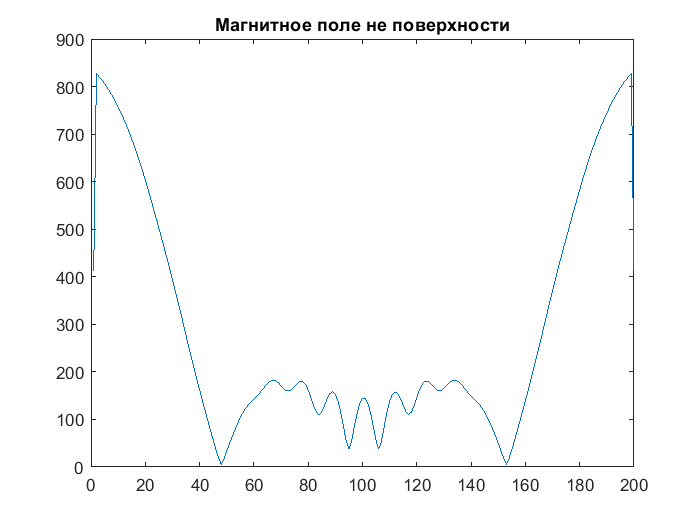

for m  = 1 : N_point
    xm = x_see(m);
    zm = z_see(m);
    txm = tx(m);
    tzm = tz(m);
    nxm = nx(m);
    nzm = nz(m);
    n_for_graf(m) = m;
    
    H_surf_n = 0;
    for n = 1 : N
        xn = x_midle(n);
        zn = z_midle(n);
        txn = tx(n);
        tzn = tz(n);
        nxn = nx(n);
        nzn = nz(n);
%         dx = dx_mass(n);
            
        % Растояние между началом координат О2 и точкой наблюдений (в ГСК)        
        x_mO2 = xm - xn;
        z_mO2 = zm - zn;
        
        % Положим этот вектор на новую СК
        % Координаты этой точки (в ЛСК)
        umn = x_mO2*txn + z_mO2*tzn;
        wmn = x_mO2*nxn + z_mO2*nzn;
        
        % локальные замены 
        xmn = xm - xn;
        zmn = zm - zn;
        r = sqrt(xmn^2 + zmn^2);
        
        umn_plus = umn + dx/2;
        umn_minus = umn - dx/2; 
        r_minus = sqrt(umn_minus^2 + wmn^2);
        r_plus = sqrt(umn_plus^2 + wmn^2);
        rmn = sqrt(umn^2 + wmn^2);
        
        Hus = 0;
        Hws = 0;
        
        if n == m 
            % cоставляющие Hy1
            he_y1 =  - 1/2;
        elseif abs(n-m) <= 1.5 
            he_y1 =  - (1i/8*wmn*k^2*dx + 1/(2*pi)*(atan(umn_plus/wmn) - atan(umn_minus/wmn)));
        else 
            % cоставляющие Hy1
            he_y1 = - 1i/4*k*dx*(wmn/rmn*besselh(1,1,k*rmn));
        end
        H1y = he_y1;
        
        % расчет матричнх элементов 
        H_surf_n = H_surf_n + (H1y)*I_Ae_MFIE(n);
    end
    H_surf(m) = H_surf_n;
end

figure;
plot(n_for_graf, abs(H_surf));
title('Магнитное поле не поверхности'); 

#### Поле Am MFIE

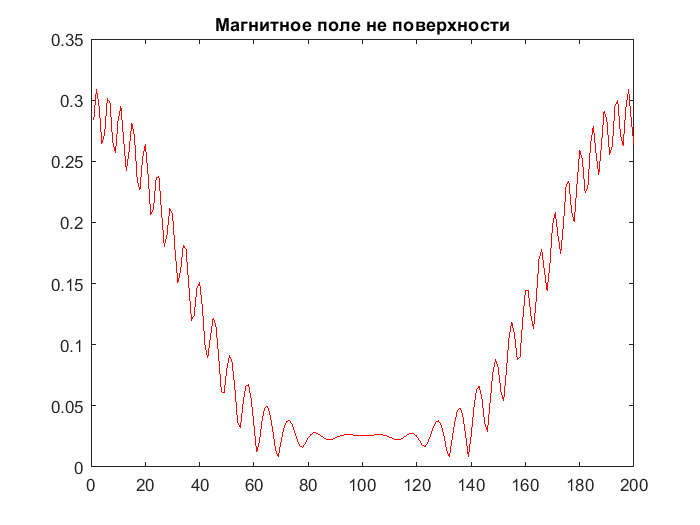

% for m  = 1 : N_point
%     xm = x_see(m);
%     zm = z_see(m);
%     txm = tx(m);
%     tzm = tz(m);
%     nxm = nx(m);
%     nzm = nz(m);
%     n_for_graf(m) = m;
%     
%     H_surf_n = 0;
%     for n = 1 : N
%         xn = x_midle(n);
%         zn = z_midle(n);
%         txn = tx(n);
%         tzn = tz(n);
%         nxn = nx(n);
%         nzn = nz(n);
% %         dx = dx_mass(n);
%             
%         % Растояние между началом координат О2 и точкой наблюдений (в ГСК)        
%         x_mO2 = xm - xn;
%         z_mO2 = zm - zn;
%         
%         % Положим этот вектор на новую СК
%         % Координаты этой точки (в ЛСК)
%         umn = x_mO2*txn + z_mO2*tzn;
%         wmn = x_mO2*nxn + z_mO2*nzn;
%         
%         % локальные замены 
%         xmn = xm - xn;
%         zmn = zm - zn;
%         r = sqrt(xmn^2 + zmn^2);
%         
%         umn_plus = umn + dx/2;
%         umn_minus = umn - dx/2; 
%         r_minus = sqrt(umn_minus^2 + wmn^2);
%         r_plus = sqrt(umn_plus^2 + wmn^2);
%         rmn = sqrt(umn^2 + wmn^2);
% 
%         if n == m 
%             % cоставляющие Hy1
%             hm_y1 = 1i/4*dx*(1 + 1i*2/pi*(log(gamma*k*dx/4)-1));
%         else 
%             % cоставляющие Hy1
%             hm_y1 = 1i/4*dx*besselh(0,1,k*rmn);
%         end
%         H1y = 1i*k/eta*hm_y1;
%        
%         H_surf_n = H_surf_n + H1y*I_Am_MFIE(n);
%     end
%     H_surf(m) =  H_surf_n;
% end
% 
% figure;
% plot(n_for_graf, abs(H_surf), 'r');
% title('Магнитное поле не поверхности'); 